10.6（`特征值的灵敏度和精度`）实时脚本

由张志涌编写、修改于 2023.1。

format shorte
A = gallery(3)

A =   -149   -50  -154
   537   180   546
   -27    -9   -25


[X,lambda] = eig(A);
condest(X)

ans =    1.2002e+03


format short
A = gallery(3)

A =   -149   -50  -154
   537   180   546
   -27    -9   -25


lambda = eig(A)

lambda =     1.0000
    2.0000
    3.0000


kappa = condeig(A)

kappa =   603.6390
  395.2366
  219.2920


rng('default')		%为以下结果可重现而设
format long
delta = 1.e-6;
lambda = eig(A + delta*randn(3,3))

lambda =    0.999992726243023
   2.000126280339932
   2.999885428246349


lambda-(1:3)'

ans = 1.0e-03 *

  -0.007273756976733
   0.126280339932006
  -0.114571753650594


delta*condeig(A)

ans = 1.0e-03 *

   0.603638964951295
   0.395236637984600
   0.219292042718589


format short
A = gallery(5)

A =           -9          11         -21          63        -252
          70         -69         141        -421        1684
        -575         575       -1149        3451      -13801
        3891       -3891        7782      -23345       93365
        1024       -1024        2048       -6144       24572


lambda = eig(A)

lambda =   -0.0347 + 0.0258i
  -0.0347 - 0.0258i
   0.0138 + 0.0401i
   0.0138 - 0.0401i
   0.0419 + 0.0000i


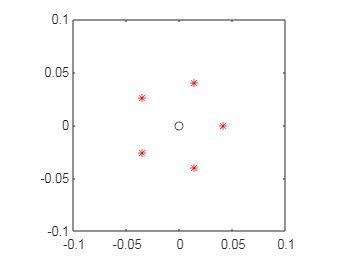

A = gallery(5);
e = eig(A);
plot(real(e),imag(e),'r*',0,0,'ko')
axis(.1*[-1 1 -1 1])
axis square

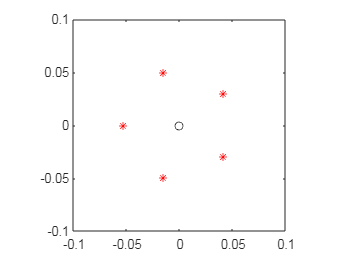

e = eig(A + eps*randn(5,5).*A);plot(real(e),imag(e),'r*',0,0,'ko'),axis(.1*[-1 1 -1 1]),axis square